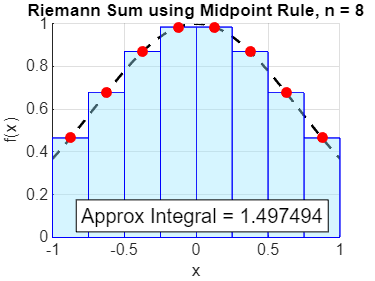

clc; clear;

% Function to integrate
f = @(x) exp(-x.^2);  % Try other functions like sin(pi*x), x.^2, etc.

% Number of rectangles (subintervals)
n = 8;

% Domain
a = -1; b = 1;
x = linspace(a, b, n+1);         % Edges of intervals
dx = (b - a)/n;                  % Uniform width
midpoints = (x(1:end-1) + x(2:end)) / 2;  % Midpoints of intervals
heights = f(midpoints);         % Function values at midpoints

% Plot setup
figure; hold on; grid on;
fplot(f, [a, b], 'k--', 'LineWidth', 1.5); % Plot actual function
xlabel('x'); ylabel('f(x)');
title(['Riemann Sum using Midpoint Rule, n = ', num2str(n)]);

% Draw rectangles
for i = 1:n
    x_left = x(i);
    x_right = x(i+1);
    x_rect = [x_left, x_right, x_right, x_left];
    y_rect = [0, 0, heights(i), heights(i)];

    fill(x_rect, y_rect, [0.6 0.9 1], 'EdgeColor', 'b', 'FaceAlpha', 0.4);
end

% Plot midpoints
plot(midpoints, heights, 'ro', 'MarkerFaceColor', 'r');

% Display approximate integral
I_approx = sum(heights * dx);
text(-0.8, 0.1, sprintf('Approx Integral = %.6f', I_approx), ...
     'FontSize', 12, 'BackgroundColor', 'w', 'EdgeColor', 'k');